# Character Recognition

This example illustrates how to train a neural network to perform simple character recognition.

## Defining the Problem

The script `prprob` defines a matrix 7 with 5 columns, one for each number. Each matrix has 35 values which can either be 1 or 0. Each matrix of 35 values defines a 5x7 bitmap of a number.

The matrix `T` is a 5x7 identity matrix which maps the 35 input vectors to the 35 classes.

[X,T] = numberVariations;

Here is the first number, note that numbers are randomized so this is going to be a random number, is plotted as a bit map.

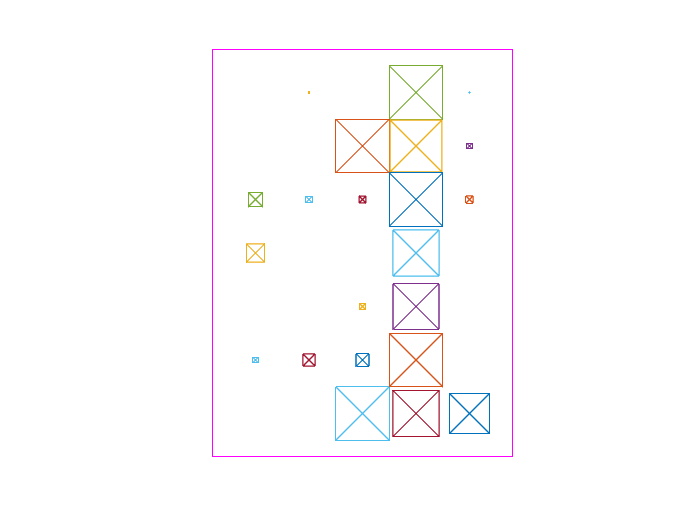

plotchar(X(:,1))

disp(T(:,1))

     1



## Creating the Neural Networks

To solve this problem we will use feedforward neural networks set up for pattern recognition with different hidden neurons and layers, and after wards we will take a majority vote for the answer.

Since the neural network is initialized with random initial weights, the results after training vary slightly every time the example is run, we will use 'trainrp' resilient backpropagation algorithm for it's good performance time and output.

% setdemorandstream(pi);

net1 = feedforwardnet([65 65 65],'trainrp');%train using resilient backpropagation algorithm
net1.layers{1}.transferFcn = 'softmax';
net1.layers{2}.transferFcn = 'softmax';
net1.layers{3}.transferFcn = 'softmax';
net1.layers{4}.transferFcn = 'tansig';
%view(net1)
net1.trainParam.max_fail=1000;%maximum number of validation checks 1000

%%%%Net2%%%
net2 = feedforwardnet([32 65 32],'trainrp');
net2.layers{1}.transferFcn = 'softmax';
net2.layers{2}.transferFcn = 'softmax';
net2.layers{3}.transferFcn = 'softmax';
net2.layers{4}.transferFcn = 'tansig';
net2.trainParam.max_fail=1000;

%%%%Net3%%%
net3 = feedforwardnet([35 122 35],'trainrp');
net3.layers{1}.transferFcn = 'softmax';
net3.layers{2}.transferFcn = 'softmax';
net3.layers{3}.transferFcn = 'softmax';
net3.layers{4}.transferFcn = 'tansig';
net3.trainParam.max_fail=1000;

%%%%Net4%%%
net4 = feedforwardnet([35 35],'trainrp');
net4.layers{1}.transferFcn = 'softmax';
net4.layers{2}.transferFcn = 'softmax';
net4.layers{3}.transferFcn = 'tansig';
net4.trainParam.max_fail=1000;

%%%%Net5%%%
net5 = feedforwardnet([65],'trainrp');
net5.layers{1}.transferFcn = 'softmax';
net5.layers{2}.transferFcn = 'tansig';
net5.trainParam.max_fail=1000;

%%%%Net6%%%
net6 = feedforwardnet([32 40],'trainrp');
net6.layers{1}.transferFcn = 'softmax';
net6.layers{2}.transferFcn = 'softmax';
net6.layers{3}.transferFcn = 'tansig';
net6.trainParam.max_fail=1000;

%%%%Net7%%%
net7 = feedforwardnet([12 12],'trainrp');
net7.layers{1}.transferFcn = 'softmax';
net7.layers{2}.transferFcn = 'softmax';
net7.layers{3}.transferFcn = 'tansig';
% net7.layers{4}.transferFcn = 'softmax';
% net7.layers{5}.transferFcn = 'softmax';
% net7.layers{6}.transferFcn = 'tansig';
net7.trainParam.max_fail=1000;

%%%%Net8%%%
net8 = feedforwardnet([128 66 128],'trainrp');%keep
net8.layers{1}.transferFcn = 'softmax';
net8.layers{2}.transferFcn = 'softmax';
net8.layers{3}.transferFcn = 'softmax';
net8.layers{4}.transferFcn = 'tansig';
net8.trainParam.max_fail=1000;

%%%%Net9%%%
net9 = feedforwardnet([128],'trainrp');
net9.layers{1}.transferFcn = 'softmax';
net9.layers{2}.transferFcn = 'tansig';
% net9.layers{3}.transferFcn = 'softmax';
% net9.layers{4}.transferFcn = 'softmax';
% net9.layers{4}.transferFcn = 'softmax';
% net9.layers{5}.transferFcn = 'softmax';
% net9.layers{6}.transferFcn = 'tansig';
net9.trainParam.max_fail=1000;

## Training the Neural Networks

The function `train` divides up the data into training, validation and test sets. The training set is used to update the network, the validation set is used to stop the network before it overfits the training data, thus preserving good generalization. The test set acts as a completely independent measure of how well the network can be expected to do on new samples.

Training stops when the network is no longer likely to improve on the training or validation sets.

%net1.divideFcn = '';
  %net1.divideParam.trainRatio = 90/100;
  %net1.divideParam.testRatio = 5/100;
  %net1.divideParam.valRatio = 5/100;
 net1.trainParam.epochs=100000;
net1 = train(net1,X,T,'useParallel','yes');
pause();

%%%Net2%%%%
 net2.trainParam.epochs=100000;
net2 = train(net2,X,T,'useParallel','yes');
pause();
%%%Net3%%%%
 net3.trainParam.epochs=100000;
net3 = train(net3,X,T,'useParallel','yes');
pause();
%%%Net4%%%%
 net4.trainParam.epochs=100000;
net4 = train(net4,X,T,'useParallel','yes');
pause();
%%%Net5%%%%
 net5.trainParam.epochs=100000;
net5 = train(net5,X,T,'useParallel','yes');
pause();
%%%Net6%%%%
net6.trainParam.epochs=100000;
net6= train(net6,X,T,'useParallel','yes');
pause();
%%%Net7%%%%
net7.trainParam.epochs=100000;
net7= train(net7,X,T,'useParallel','yes');
pause();
%%%Net8%%%%
net8.trainParam.epochs=100000;
net8= train(net8,X,T,'useParallel','yes');
pause();
%%%Net9%%%%
 net9.trainParam.epochs=100000;
net9 = train(net9,X,T,'useParallel','yes');
